# Ceramic Tile Crack Identification and Detection

Dinesh Varma Dandu

Mini Project

clc
clear
close all

I=uigetfile('*.jpg','select a tile');
I = imread(I);
if size(I,3)>1
    I=rgb2gray(I);
    
end

## contrast enhancement

A=adapthisteq(I,'clipLimit',0.02,'Distribution','rayleigh');

## denosing

M=medfilt2(A,[3 3]);

## edge detection

edge=edge(M,'canny');

## morphing

s=bwmorph(edge,'skel');
f=strel('line',2,7);
s1=imdilate(s,f);
M1=imcrop(s1,[25 204 75 203]);
[x,y]=size(M1);

## final o/p

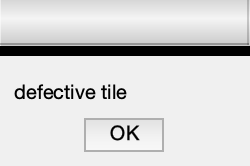

Error using fclose
Invalid file identifier. Use fopen to generate a valid file identifier.

count=1;
for ii=1:x
    for jj=1:y
        if M1(ii,jj)==1
            count=count+1;
        end
    end
end
if count>900
    msgbox('defective tile')
    if (exist('s'))
        fclose(s)
        delete(s)
        clear s
    end
    s=serial('COM16','BaudRate',9600);
    fopen(s);
    fprintf(s,'Y');
else
    msgbox('perfect tile')
    
    s=serial('COM16','BaudRate',9600);
    fopen(s);
    fprintf(s,'N');
end